HW 3 - Problem 4

h =

`�`

1 1.451  ́1.668  ́4.757  ́2.402 2.555 3.800 0.928  ́1.209  ́0.727

`�`

Write a MATLAB code which takes this h and (a valid noisy filter output) ˆy as

inputs, and generates an estimate (call it ˆx) of the input signal x by implementing

the technique that you proposed in part (c). Vary the input noise: start from n = 0

and then increase the noise level. You are free to choose the distribution of the noise.

Test your code with the following input signal x:

h = [1 1.451 -1.668 -4.757 -2.402 2.555 3.800 .928 -1.209 -.727]

h =     1.0000    1.4510   -1.6680   -4.7570   -2.4020    2.5550    3.8000    0.9280   -1.2090   -0.7270



x = [0 .2778 .5556 -.7375 -.4597 -.1819 0.0959 .3736 .6514 -.6416]

x =          0    0.2778    0.5556   -0.7375   -0.4597   -0.1819    0.0959    0.3736    0.6514   -0.6416


m = max(size(x))

m = 10

n= max(size(h))

n = 10

k = n + m -1

k = 19

y = conv(h,x)

y =          0    0.2778    0.9587   -0.3947   -3.7780   -2.9290    3.4823    7.2496    3.4878   -4.1362   -7.7948   -3.3110    3.7295    5.2682    1.1990   -2.3550   -1.6546    0.3021    0.4664




H =top(h,x)

H =     1.0000         0         0         0         0         0         0         0         0         0
    1.4510    1.0000         0         0         0         0         0         0         0         0
   -1.6680    1.4510    1.0000         0         0         0         0         0         0         0
   -4.7570   -1.6680    1.4510    1.0000         0         0         0         0         0         0
   -2.4020   -4.7570   -1.6680    1.4510    1.0000         0         0         0         0         0
    2.5550   -2.4020   -4.7570   -1.6680    1.4510    1.0000         0         0         0         0
    3.8000    2.5550   -2.4020   -4.7570   -1.6680    1.4510    1.0000         0         0         0
    0.9280    3.8000    2.5550   -2.4020   -4.7570   -1.6680    1.4510    1.0000         0         0
   -1.2090    0.9280    3.8000    2.5550   -2.4020   -4.7570   -1.6680    1.4510    1.0000         0
   -0.7270   -1.2090    0.9280    3.8000    2.5550   -2.4020   -4.7570   -1.6680    1.4

y_test = H*transpose(x)

y_test =          0
    0.2778
    0.9587
   -0.3947
   -3.7780
   -2.9290
    3.4823
    7.2496
    3.4878
   -4.1362


H

H =     1.0000         0         0         0         0         0         0         0         0         0
    1.4510    1.0000         0         0         0         0         0         0         0         0
   -1.6680    1.4510    1.0000         0         0         0         0         0         0         0
   -4.7570   -1.6680    1.4510    1.0000         0         0         0         0         0         0
   -2.4020   -4.7570   -1.6680    1.4510    1.0000         0         0         0         0         0
    2.5550   -2.4020   -4.7570   -1.6680    1.4510    1.0000         0         0         0         0
    3.8000    2.5550   -2.4020   -4.7570   -1.6680    1.4510    1.0000         0         0         0
    0.9280    3.8000    2.5550   -2.4020   -4.7570   -1.6680    1.4510    1.0000         0         0
   -1.2090    0.9280    3.8000    2.5550   -2.4020   -4.7570   -1.6680    1.4510    1.0000         0
   -0.7270   -1.2090    0.9280    3.8000    2.5550   -2.4020   -4.7570   -1.6680    1.4

inv_H = inv(transpose(H)*H)*transpose(H)

inv_H =     0.3120   -0.1718   -0.3280   -0.0718   -0.1327   -0.0216   -0.0149   -0.0747    0.1160   -0.0708    0.0362    0.0939   -0.0417    0.0438    0.0786   -0.0549    0.0183   -0.0771    0.0282
   -0.6244    0.6509    0.4990   -0.1900    0.2020   -0.0989   -0.0013    0.1430   -0.3307    0.2493   -0.1373   -0.1844    0.1769   -0.1308   -0.1295    0.1899   -0.0707    0.2032   -0.1240
    1.0984   -1.2079   -0.5664    0.2714   -0.6935    0.1676   -0.1095   -0.3011    0.6557   -0.5428    0.3506    0.3366   -0.3290    0.3372    0.2162   -0.3289    0.1628   -0.4765    0.2606
   -1.2231    1.7271    0.2093   -0.3379    0.8679   -0.6964    0.1379    0.2605   -0.9750    0.8551   -0.6298   -0.3187    0.4954   -0.5134   -0.1189    0.4445   -0.2085    0.7476   -0.4990
    1.2531   -1.8275    0.1583    0.0224   -1.0171    0.9489   -0.5873   -0.3097    1.1461   -1.1095    0.8955    0.3241   -0.4771    0.6954    0.0858   -0.3643    0.1500   -1.0591    0.6920
   -0.9519    1.6587   -0.4781    0.2


errors_1 = zeros(1,7)

errors_1 =      0     0     0     0     0     0     0


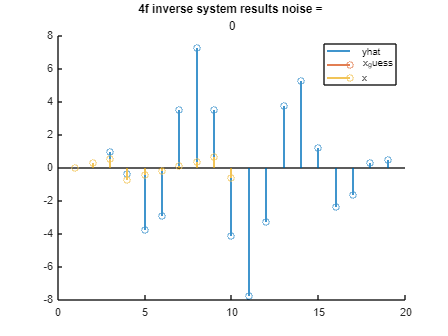

errors_1 =     4.6460         0         0         0         0         0         0


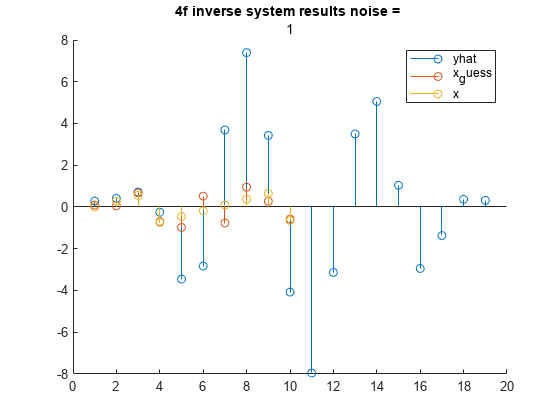

errors_1 =     4.6460    6.3970         0         0         0         0         0


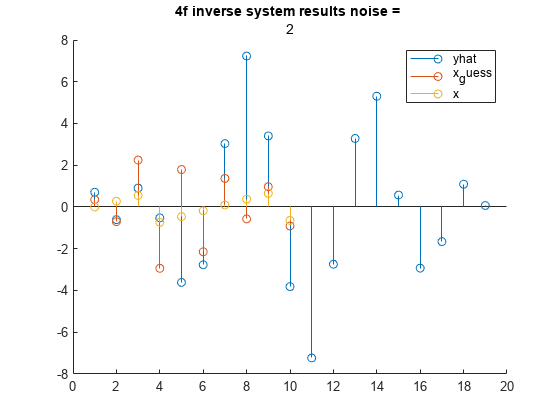

errors_1 =     4.6460    6.3970   16.1535         0         0         0         0


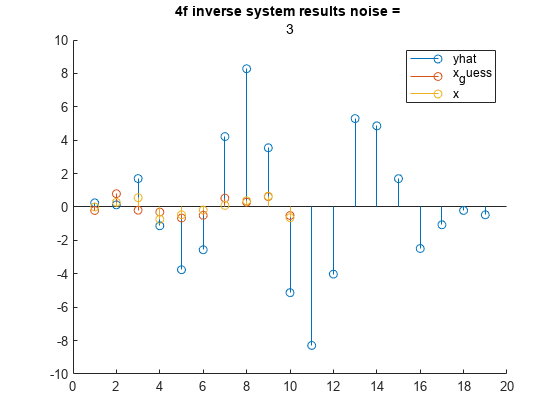

errors_1 =     4.6460    6.3970   16.1535    4.9944         0         0         0


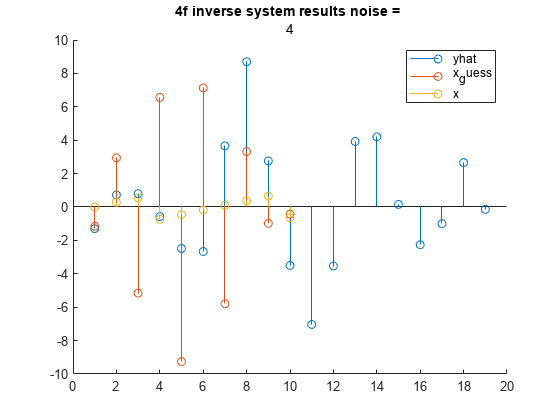

errors_1 =     4.6460    6.3970   16.1535    4.9944   51.1741         0         0


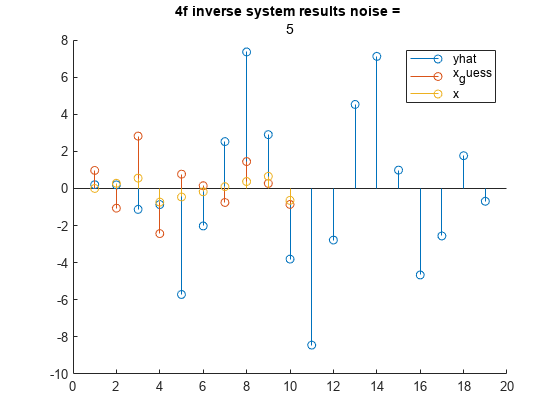

errors_1 =     4.6460    6.3970   16.1535    4.9944   51.1741   14.1778         0


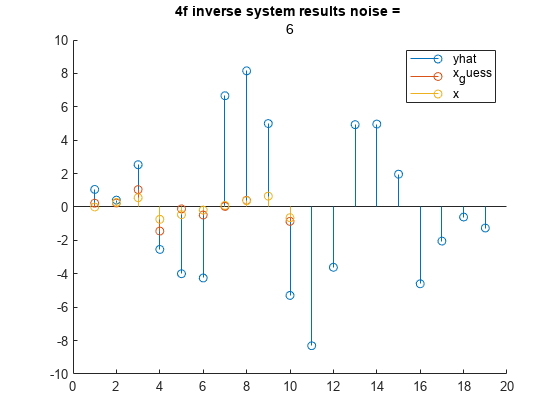

errors_1 =     4.6460    6.3970   16.1535    4.9944   51.1741   14.1778    6.9585


for l = 0:1:6
    
    noise = normrnd(0,1,size(y));
    y_hat = y + noise/norm(noise)*l;
    x_guess = inv_H*transpose(y_hat);
    figure
    hold on
    stem(1:1:19,y_hat)
    
    stem(1:10,x_guess)
    stem(1:1:10,x)
    legend('yhat','x_guess','x')
    title('4f inverse system results noise = ', string(l))
    errors_1(1,l+1) = norm(x-x_guess)
end 



eq(x,transpose(x_guess))

ans = 1×10 logical array
   0   0   0   0   0   0   0   0   0   0



noise = normrnd(0,1,size(y));
y_hat = y 

y_hat =          0    0.2778    0.9587   -0.3947   -3.7780   -2.9290    3.4823    7.2496    3.4878   -4.1362   -7.7948   -3.3110    3.7295    5.2682    1.1990   -2.3550   -1.6546    0.3021    0.4664


    
e_1 = zeros(1,k);
e_1(1) = 1;


h_tilde = inv_H*transpose(e_1)

h_tilde =     0.3120
   -0.6244
    1.0984
   -1.2231
    1.2531
   -0.9519
    0.6864
   -0.3585
    0.1706
   -0.0388


k_new = k + n - 1

k_new = 28

H_tilde = zeros(k+n-1,k)

H_tilde =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0    


for i=1:1:m
    for j=1:1:max(size(h_tilde))
        H_tilde(i+j-1,i) = h_tilde(j,1);
        
    end
end
H_tilde

H_tilde =     0.3120         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.6244    0.3120         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.0984   -0.6244    0.3120         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -1.2231    1.0984   -0.6244    0.3120         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.2531   -1.2231    1.0984   -0.6244    0.3120         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.9519    1.2531   -1.2231    1




e_1 = zeros(1,m);
e_1(1) = 1;
test = H*transpose(e_1)

test =     1.0000
    1.4510
   -1.6680
   -4.7570
   -2.4020
    2.5550
    3.8000
    0.9280
   -1.2090
   -0.7270



y_hat = conv(x,h)

y_hat =          0    0.2778    0.9587   -0.3947   -3.7780   -2.9290    3.4823    7.2496    3.4878   -4.1362   -7.7948   -3.3110    3.7295    5.2682    1.1990   -2.3550   -1.6546    0.3021    0.4664




%result1 = y_hat*H_tilde
result2 = H_tilde*transpose(y_hat)

result2 =          0
    0.0867
    0.1256
   -0.4166
   -0.2189
    0.1874
    0.1852
    0.2744
    0.1685
   -0.4057


x

x =          0    0.2778    0.5556   -0.7375   -0.4597   -0.1819    0.0959    0.3736    0.6514   -0.6416


  
    
    
    
errors_2 = zeros(1,7)

errors_2 =      0     0     0     0     0     0     0


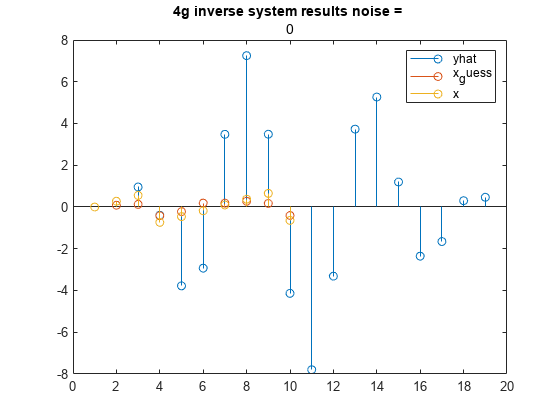

errors_2 =    32.8956         0         0         0         0         0         0


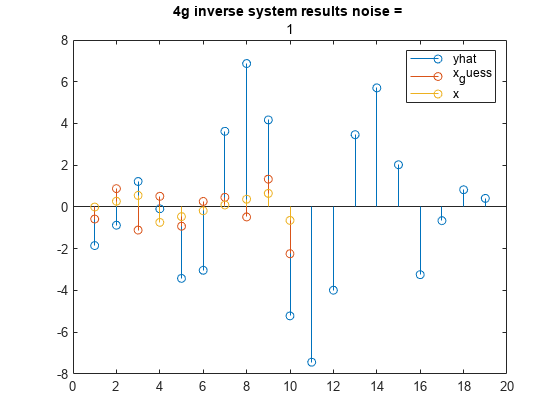

errors_2 =    32.8956   50.8100         0         0         0         0         0


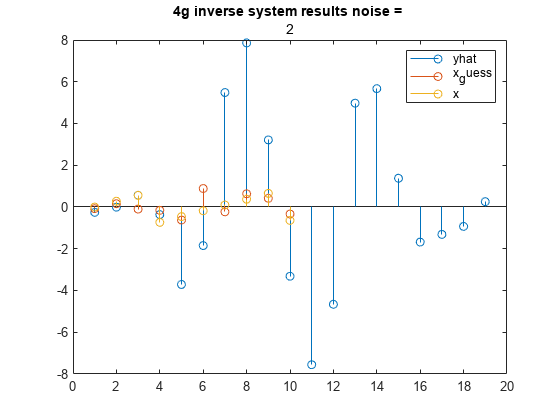

errors_2 =    32.8956   50.8100   26.7592         0         0         0         0


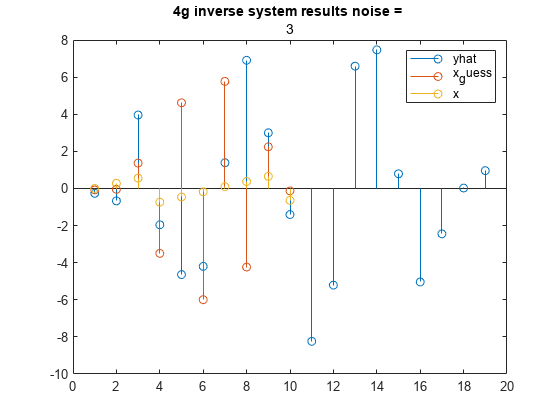

errors_2 =    32.8956   50.8100   26.7592   36.3997         0         0         0


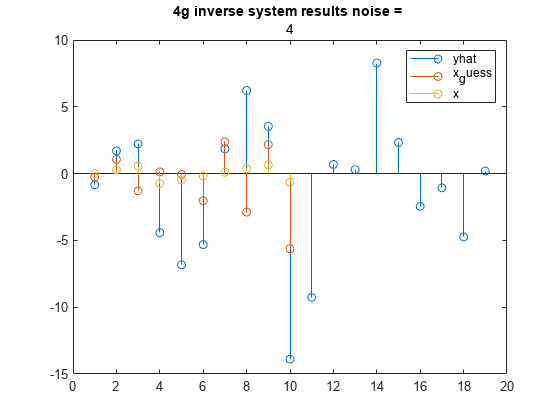

errors_2 =    32.8956   50.8100   26.7592   36.3997  115.9794         0         0


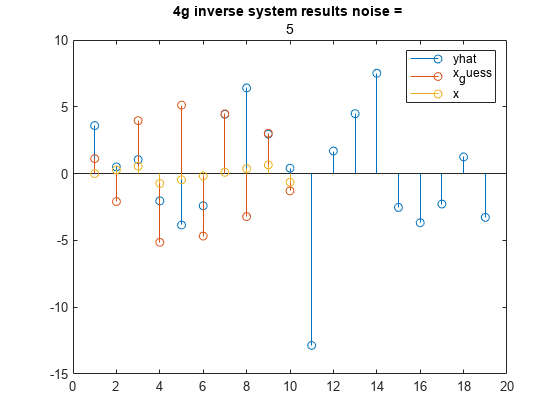

errors_2 =    32.8956   50.8100   26.7592   36.3997  115.9794   37.2971         0


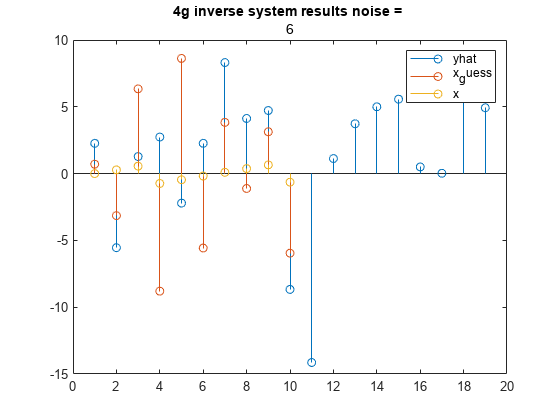

errors_2 =    32.8956   50.8100   26.7592   36.3997  115.9794   37.2971  117.4331


for l = 0:1:6
    
    noise = normrnd(0,1,size(y));
    y_hat = y + noise./max(noise).*l;
    x_guess = H_tilde*transpose(y_hat);
    figure
    stem(1:1:19,y_hat)
    hold on
    stem(1:10,x_guess(1:10))
    stem(1:1:10,x)
    legend('yhat','x_guess','x')
    title('4g inverse system results noise = ', string(l))
    errors_2(1,1+l) = norm(x_guess-x)
end 

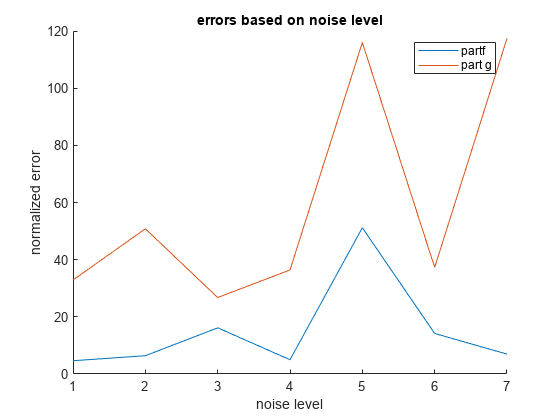


    
    figure(100)
hold on
    plot(errors_1)
    plot(errors_2)
    legend('partf','part g')
    title('errors based on noise level')
    xlabel('noise level')
    ylabel('normalized error')
    hold off

function ret = top(h,x)
    x_dim = max(size(x));
    h_dim = max(size(h));
    k = x_dim + h_dim - 1;
    ret = zeros(k,x_dim);
    for i = 1:1:x_dim
        for j = 1:1:h_dim
            ret(i+j-1,i) = h(j);
        end
    end
end